# Esercizio 5

f = @(x) (x + exp( 1./( 1+x.^2 ) ) )

f = function_handle with value:
    @(x)(x+exp(1./(1+x.^2)))



a = -2; b = 2;
xx = linspace(a,b,100);
n = [6:2:10]';
xx6 = linspace(a, b, n(1));
xx8 = linspace(a, b, n(2));
xx10 = linspace(a, b, n(3));

y6=f(xx6)

y6 =    -0.7786    0.3066    1.9681    2.7681    2.7066    3.2214


y8=f(xx8)

y8 =    -0.7786   -0.0392    0.9226    2.2350    2.8064    2.6369    2.8180    3.2214


y10=f(xx10)

y10 =    -0.7786   -0.2159    0.4533    1.3317    2.3711    2.8155    2.6650    2.6755    2.8952    3.2214


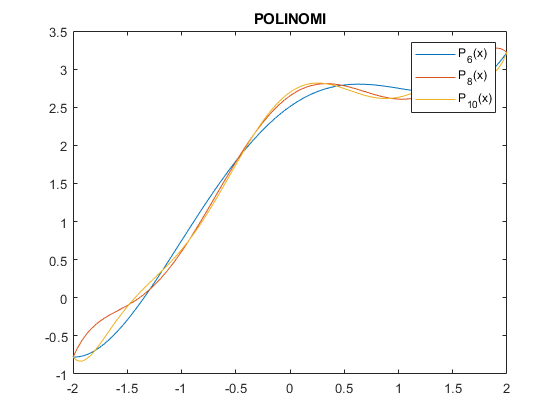


[yy6,p6] = pol_lagrange(xx6,y6,xx);
[yy8,p8] = pol_lagrange(xx8,y8,xx);
[yy10,p10] = pol_lagrange(xx10,y10,xx);
figure
plot(xx,[yy6' yy8' yy10']);
title("POLINOMI");
y=f(xx);
legend("P_{6}(x)","P_{8}(x)","P_{10}(x)")

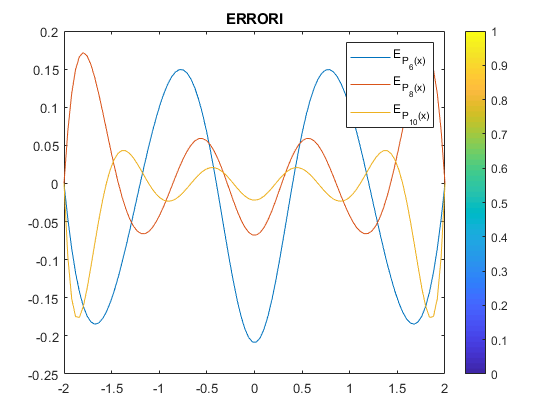


plot(xx,[(yy6-y)' (yy8-y)' (yy10-y)']);
title("ERRORI")
legend("E_{P_{6}(x)}","E_{P_{8}(x)}","E_{P_{10}(x)}")